# Estimating Phase for the EEG mu-rhythm

This is a small demonstration of the SSPE (State Space Phase Estimation) algorithm when applied to open-source EEG data acquired from the C3 electrode showing prominent mu-rhythm bursts. 

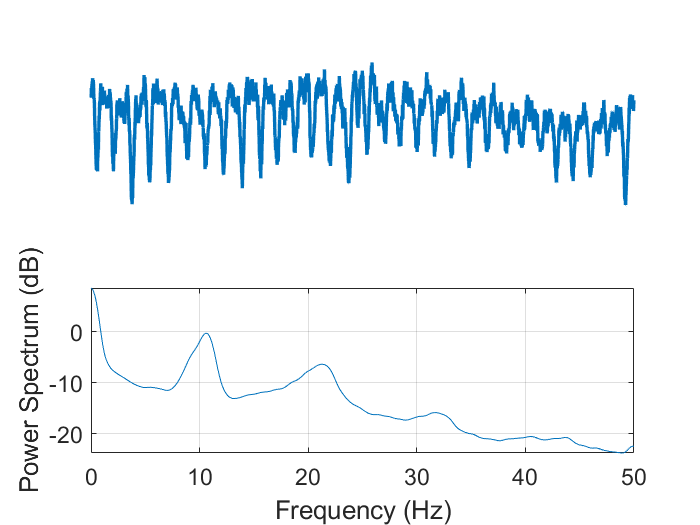

%%
Fs = 1000;
load('eg_muRhythmData.mat')
% plotting mu-rhythm data:
figure
subplot(211)
plot(.001:.001:3, data(9001:12000),'Linewidth',2)
axis off

subplot(212)
pspectrum(data,Fs)
xlim([0,50])
grid on
title('')
set(gca,'Fontsize', 14)

%%

% following helps to initialize more reasonable estimates for the scaling
% setting up a moving average to remove very slow changes, can be applied
% causally
tmpMean = conv([mean(data)*ones(1,3000),data,mean(data)*ones(1,3000)],ones(3000,1),'same')/3000;
data = data - tmpMean(1501:end-4500);

% setting up initial parameters to start the causalPhaseEM code
initParams.freqs = [2,11,22]; % setting up to estimate three oscillators - helps to account for the harmonic of the 11 Hz
initParams.Fs = 1000;
initParams.ampVec = [.99,.99,.99]; % in a pinch this can be initialized to 0.99 to start
initParams.sigmaFreqs = [.01,.01,.01]; % its important to use a value of this that is in the same ballpark scale
initParams.sigmaObs = 1;
initParams.window = 5000;
initParams.lowFreqBand = [8,14];

[phase,phaseBounds,allX_full,phaseWidth,returnParams] = causalPhaseEM_MKmdl_noSeg(data(1e4+1:2e4), initParams,0);
% note that phase, phaseBounds and allX_full are all estimates only for the band in [8 to 14]
returnParams

returnParams = struct with fields:
         freqs: [5.6824e-35 10.3744 17.7874]
        ampVec: [0.9954 1.0000 0.9807]
    sigmaFreqs: [0.0219 3.5023e-04 0.1139]
      sigmaObs: 0.3468


% Code is available at: https://github.com/wodeyara/stateSpacePhasePredictor

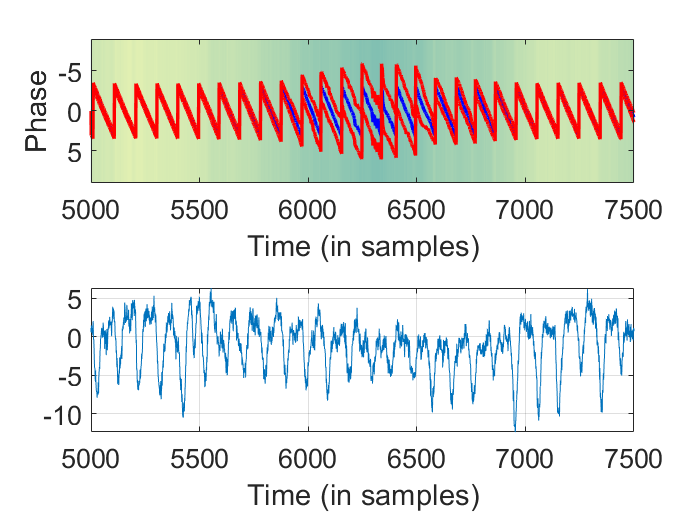


figure
subplot(211)
imagesc( 1:length(phase),-3:3, (abs(allX_full(:,1) + 1i*allX_full(:, 2)))', 'AlphaData', .5)
colormap(summer)
hold on; plot(1:length(phase), phase, 'Linewidth', 2, 'Color', 'b')
plot(squeeze(phaseBounds(:,1)), 'Linewidth', 2, 'color','r')
hold on
plot(squeeze(phaseBounds(:,2)), 'Linewidth', 2,'color','r')
set(gca,'Fontsize', 16)
xlabel('Time (in samples)')
ylabel('Phase')
% h = colorbar;
% ylabel(h,'Amplitude')
xlim([5000,7500])

subplot(212)
plot(data(5001:2e4))
grid on
set(gca,'Fontsize', 16)
xlabel('Time (in samples)')

xlim([5000,7500])